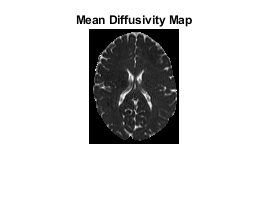

clear;
load partI.mat

%%Calculate A
A = [g(:,1).*g(:,1),g(:,2).*g(:,2),g(:,3).*g(:,3),2*g(:,1).*g(:,2),2*g(:,1).*g(:,3),2*g(:,2).*g(:,3)];

%%Error Handling
S = S.*mask;
S(S<0) = 0;
%S = abs(S) %or make the values positive

%%Calculating B
B=zeros(115,90);
for i=1:115
    for j=1:90
        for k=1:64
            B(i,j,k)=(log(S(i,j,k)/S0(i,j))/-b);
        end
    end
end

%Clearing INF values because we used log with negative values
B(isinf(B))=0;

%%Applying Mask and abs to remove complex numbers
for k=1:64
    B(:,:,k)=abs(B(:,:,k).*mask);
end

%%Calculating lots of stuff
PDDM = zeros(115,90,3);
for i=1:115
    for j=1:90
        temp=zeros(64,1);
        for k=1:64
            temp(k)=B(i,j,k);
        end
        %Calculating D
        d(:,i,j)=A\temp;
        D(:,:,i,j) = [d(1,i,j),d(4,i,j),d(5,i,j);d(4,i,j),d(2,i,j),d(6,i,j);d(5,i,j),d(6,i,j),d(3,i,j)];
        
        %Calculating MD
        [V,e]=eig(D(:,:,i,j));
        MD(i,j)=(e(1,1)+e(2,2)+e(3,3))/3;
        
        %Calculating FA
        lambda1=e(1,1);
        lambda2=e(2,2);
        lambda3=e(3,3);
        
        FA(i,j)=sqrt(((lambda1-lambda2)^2+(lambda2-lambda3)^2+(lambda1-lambda3)^2)/(2*(lambda1^2+lambda2^2+lambda3^2)));
        FA2(i,j) = (sqrt(3)/sqrt(2))*((sqrt((lambda1-MD(i,j))^2+(lambda2-MD(i,j))^2+(lambda3-MD(i,j))^2)/sqrt(lambda1^2+lambda2^2+lambda3^2)));
        %%Calculating Principle diffusion direction map
        
        %have to take the absolute of V otherwise it comes out funny
        V = abs(V);
        %Ensure that we are using the eigen vector associated with the
        %largest eigen value
        if (e(1,1)>=e(2,2) && e(1,1)>=e(3,3))
            v=V(:,1);
        elseif(e(2,2)>=e(1,1) && e(2,2)>=e(3,3))
                v=V(:,2);
        elseif(e(3,3)>=e(2,2) && e(3,3)>=e(1,1))
               v=V(:,3); 
        end

        %x,y,z vectors
        x=([1,0,0] );
        y=([0,1,0]);
        z=([0,0,1]);
        
        PDDM(i,j,1)=FA(i,j)*cos(acos(dot(v,x)/(norm(v)*norm(x))));
        PDDM(i,j,2)=FA(i,j)*cos(acos(dot(v,y)/(norm(v)*norm(y))));
        PDDM(i,j,3)=FA(i,j)*cos(acos(dot(v,z)/(norm(v)*norm(z))));
        
        %%Different way to calculate the angles
        %PDDM(i,j,1)=FA(i,j)*cos(atan2(sqrt(V(2,1)^2+V(3,1)^2),V(1,1)));
        %PDDM(i,j,2)=FA(i,j)*cos(atan2(sqrt(V(3,1)^2+V(1,1)^2),V(2,1)));
        %PDDM(i,j,3)=FA(i,j)*cos(atan2(sqrt(V(1,1)^2+V(2,1)^2),V(3,1)));
    end
end

%%Displaying
figure, imshow(MD,[min(MD(MD~=0)) abs(max(MD(MD~=0)))])
title('Mean Diffusivity Map')

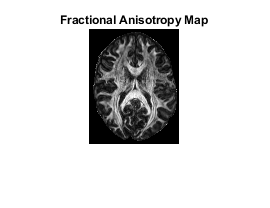

imshow(FA)
title('Fractional Anisotropy Map')

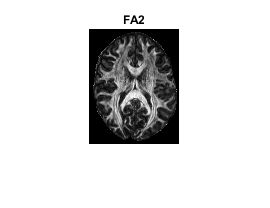

imshow(FA2)
title('FA2')

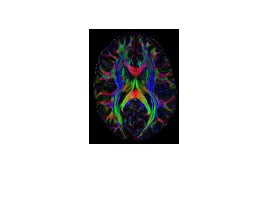

imshow(PDDM,[min(PDDM(PDDM~=0)) abs(max(PDDM(PDDM~=0)))])